Q1

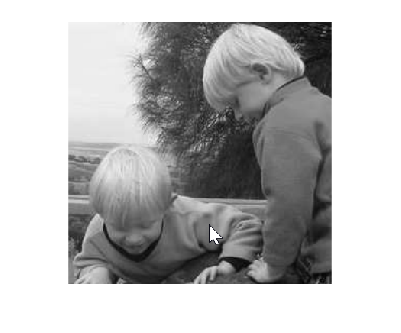

img = imread('twins.png');

imshow(img)


[rows, columns, ~] = size(img);
fprintf("Size of image is " + rows + " x " + columns);

Size of image is 343 x 345

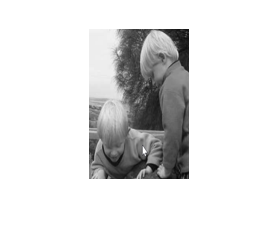


imageMag = [150 100];
img_new = imresize(img, imageMag);
imshow(img_new)


imwrite(img_new, "twins_new.png")

Q2

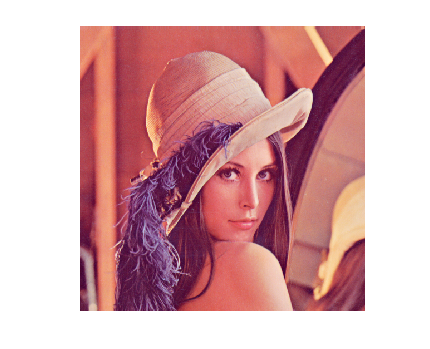

imgRGB = imread('Lenna.png');

imshow(imgRGB)


[rows, columns, ~] = size(imgRGB)

rows = 512

columns = 512

disp(['Size of image is ' , num2str(rows) , ' x ' , num2str(columns)]);

Size of image is 512 x 512


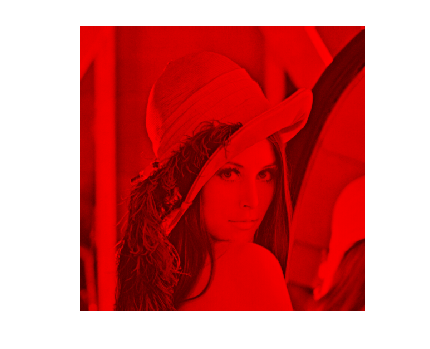


R = imgRGB;
R(:, :, [2,3]) = 0;
G = imgRGB;
G(:, :, [1,3]) = 0;
B = imgRGB;
B(:, :, [1,2]) = 0;
imshow(R)

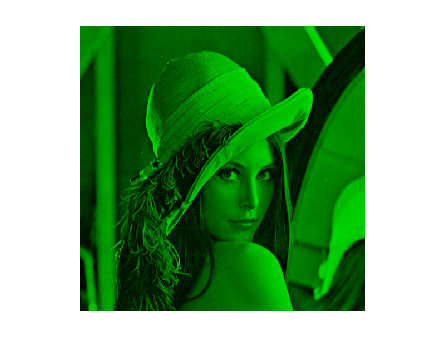

imshow(G)

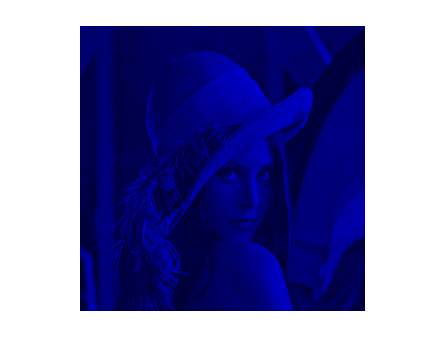

imshow(B)

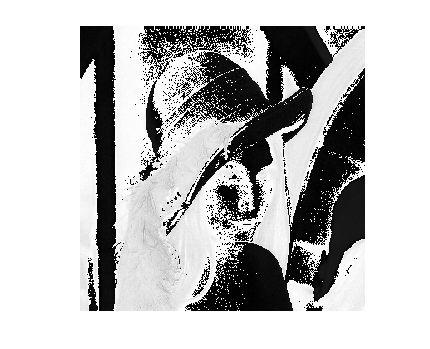


imgHSV = rgb2hsv(imgRGB);
H = imgHSV;
% A=H(:, :, 1) ;
S = imgHSV;
V = imgHSV;
imshow(H(:, :, 1))

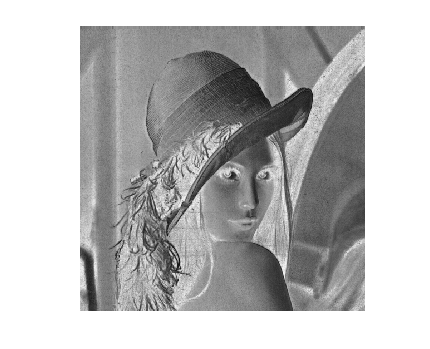

imshow(S(:, :, 2))

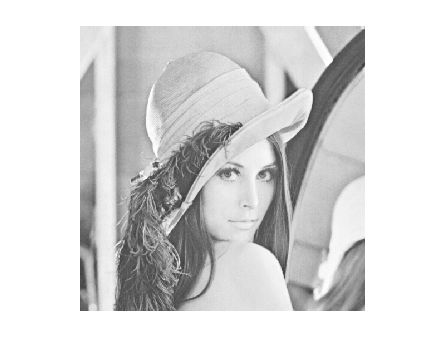

imshow(V(:, :, 3))

What does Hue, Saturation and Value(intensity) mean?

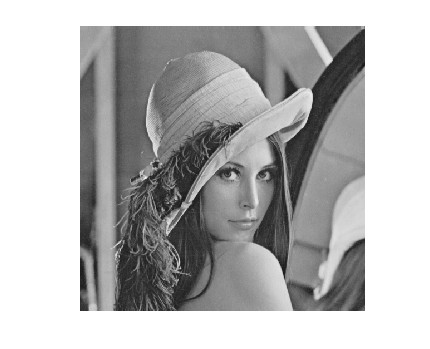

imgGrey = rgb2gray(imgRGB);
imshow(imgGrey)

maximum = max(imgGrey, [], 'all');
minimum = min(imgGrey, [], 'all');
disp(['The maximum value is ' , num2str(maximum) , ' and the minimum is ' , num2str(minimum)]);

The maximum value is 245 and the minimum is 25


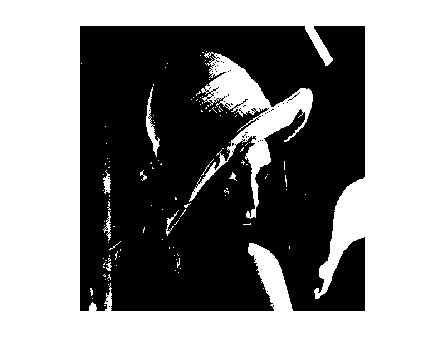


imgBin = im2bw(imgGrey, 0.7); 
imshow(imgBin)

Q3

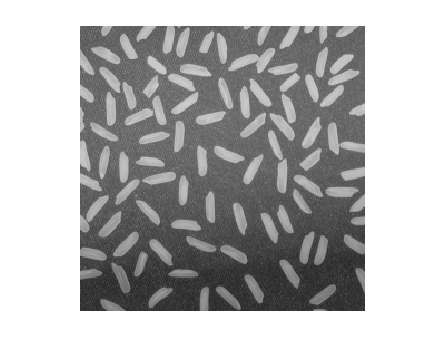

img = imread('rice.png');
imshow(img)

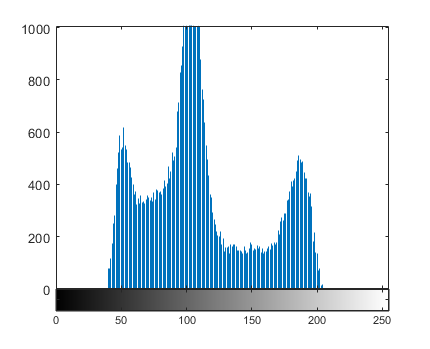


imhist(img)

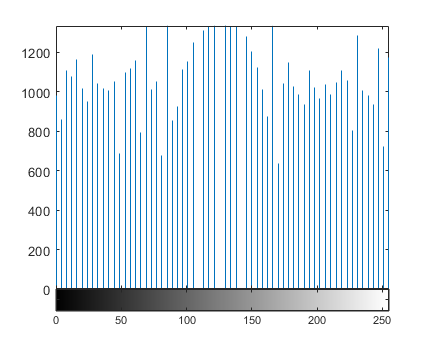


A = histeq(img);
imhist(A)

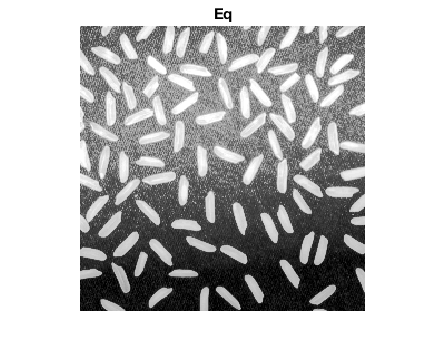


imshow(A);
title("Eq")

Q4

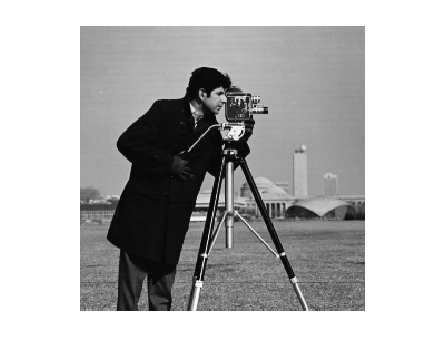

img = imread('cameraman.tif');
imshow(img)


imgBlur = imfilter(img, fspecial("average", 20))

imgBlur = 256×256 uint8 matrix
    48    52    56    61    65    69    74    78    83    87    87    87    87    87    88    88    88    88    88    88    88    89    89    89    89    89    89    90    90    90    90    90    91    91    91    91    91    92    92    92    92    92    92    93    93    93    93    93    93    93
    52    57    61    66    71    76    80    85    90    95    95    95    95    95    95    95    96    96    96    96    96    97    97    97    97    97    98    98    98    98    98    99    99    99    99    99   100   100   100   100   100   101   101   101   101   101   101   101   101   102
    56    61    66    72    77    82    87    92    98   103   103   103   103   103   103   104   104   104   104   104   104   105   105   105   105   106   106   106   106   106   107   107   107   107   107   108   108   108   108   109   109   109   109   109   109   110   110   110   110   110
    60    66    71    77    83    88    94    99   105   111   111

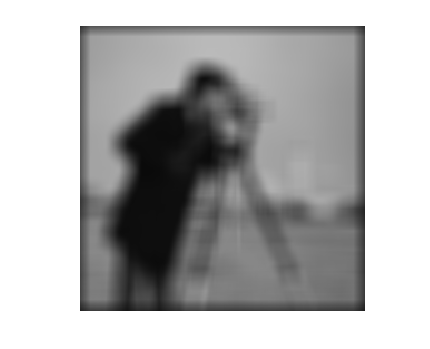

imshow(imgBlur)

Q5

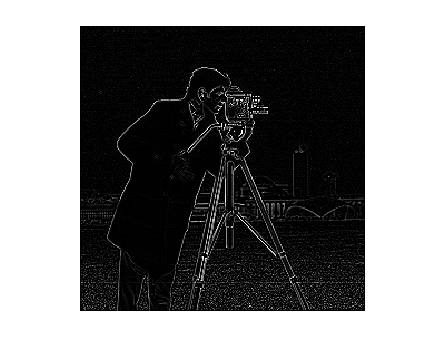

img = imread('cameraman.tif');

g=[0 1 0;1 -4 1;0 1 0];

imLap = imfilter(img,g);
imshow(imLap)

Q6

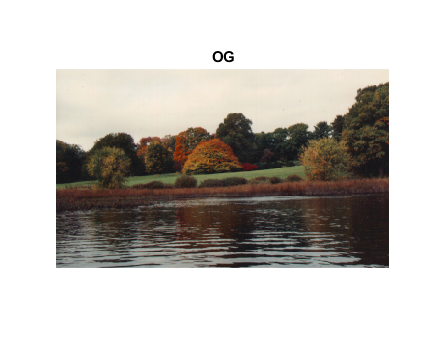

img = imread('autumn.tif');
imshow(img)
title("OG")

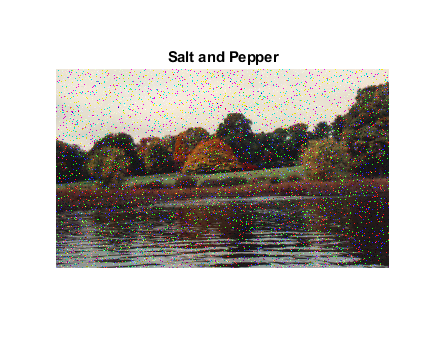


imgSP = imnoise(img, 'salt & pepper');
imshow(imgSP)
title("Salt and Pepper")

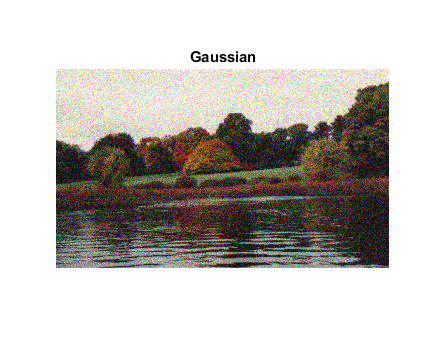


imgG = imnoise(img, 'gaussian');
imshow(imgG)
title("Gaussian")

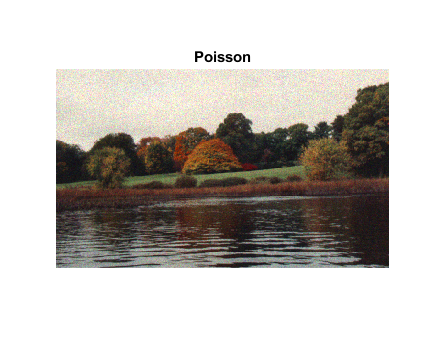


% imgP = imnoise(img, 'poisson');
% imshow(imgP)
% title("Poisson")

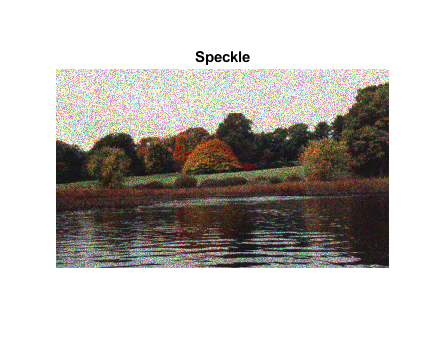


imgS = imnoise(img, 'speckle');
imshow(imgS)
title("Speckle")

Q7

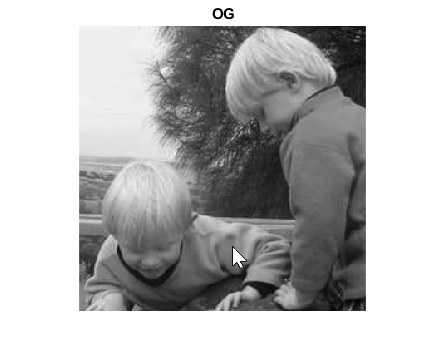

img = imread('twins.png');
imshow(img)
title("OG")

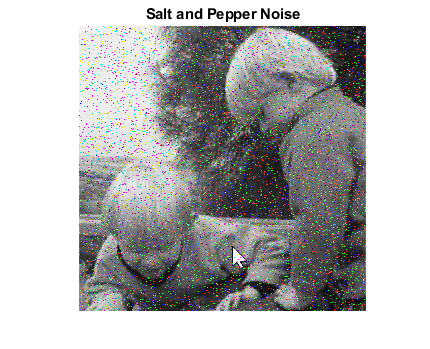


imgSP = imnoise(img, 'salt & pepper', 0.07);
imshow(imgSP)
title("Salt and Pepper Noise")

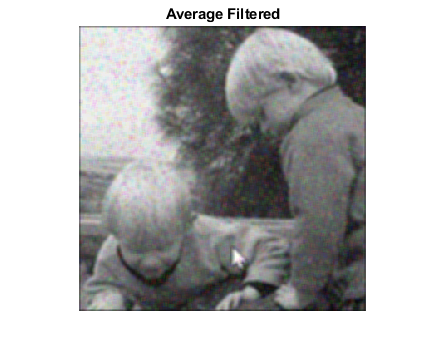


imgAvg = imfilter(imgSP, fspecial("average", 5));
imshow(imgAvg)
title("Average Filtered")

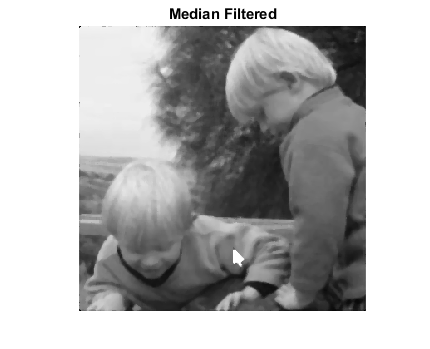


imgMed = medfilt2(rgb2gray(imgSP), [5 5]);
imshow(imgMed)
title("Median Filtered")

Q8

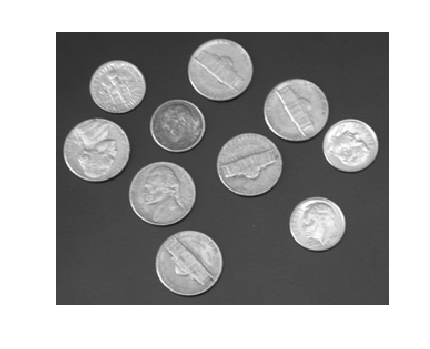

imgGray = imread('coins.png');
imshow(imgGray)

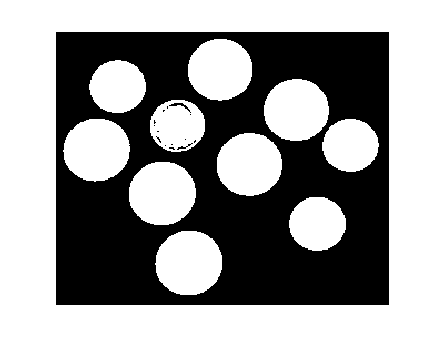


imgROI = imbinarize(imgGray, 0.4);
imshow(imgROI)

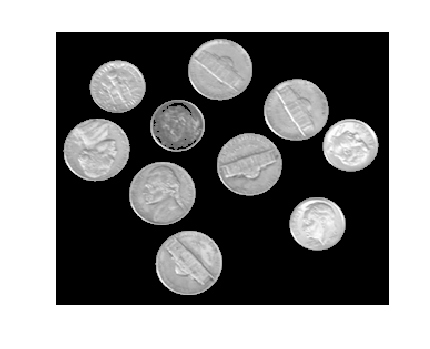


% imgSeg = imoverlay(imgGray, imgROI);
imgSeg = uint8(imgROI) .* imgGray;
imshow(imgSeg)

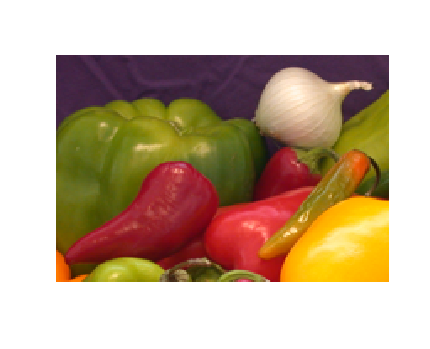

imgRGB = imread("onion.png");
imshow(imgRGB)

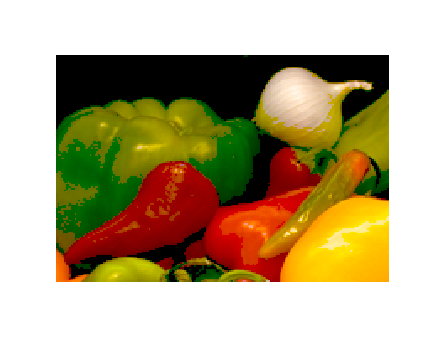


R = imgRGB(:, :, 1);
G = imgRGB(:, :, 2);
B = imgRGB(:, :, 3);

threshR = 0.4;
threshG = 0.2;
threshB = 0.5;

imgROIR = imbinarize(R, threshR);
% imshow(imgROIR)
imgSegR = uint8(imgROIR) .* R;
% imshow(imgSegR);

imgROIG = imbinarize(G, threshG);
% imshow(imgROIG)
imgSegG = uint8(imgROIG) .* G;
% imshow(imgSegG);

imgROIB = imbinarize(B, threshB);
% imshow(imgROIB)
imgSegB = uint8(imgROIB) .* B;
% imshow(imgSegB);

imgNew = cat(3, imgSegR, imgSegG, imgSegB);
imshow(imgNew)